# Tune the network for Paper 3: sharpenning tuning curve

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

FigurePaperPath = [CurrentFolder '/Figures/Demo012724/']; % V1D2
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3NWSimulationData/MoreSILGN/'];
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3NWSimulationData/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/'];
addpath(DataFolder)
addpath(DataFolder1)
% First setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2;
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

## Tuning NOW!!!

Conn_Reduc_Test = 5;

N_EE = 190-Conn_Reduc_Test; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = (255-Conn_Reduc_Test)/N_EE; % Was 250 for 071021 simulation
EcplxInd = ismember(1:N_E, N_S+1:N_E);

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR);
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI;
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR);

## 2. Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rS_amb = 0.6;
rC_amb = 0.75;
rE_amb = [rS_amb*ones(N_S,1);rC_amb*ones(N_C,1)];
rI_amb = 0.435; % was 0.435 for Fig1V4
% was 0.5 for for 071021 simulation

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

NOTE: L input is VEC now. But Fortunately can still support

% Ver1
% S_EE = 0.024; S_EI = S_EE*1.8;  % was 1.6 for for 071021 simulation
% S_II = 0.120; S_IE = S_II*0.153 * 1.6/1.8;
% Ver4
S_EE = 0.024; S_EI = S_EE*1.88;  % was 1.6 for for 071021 simulation
S_II = 0.120; S_IE = S_II*0.131;
% S_EE = 0.024; S_EI = S_EE*2.0284;  % was 1.6 for for 071021 simulation
% S_II = 0.120; S_IE = S_II*0.1183;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rL6_One = 0.007;
NS_L6 = 45; NC_L6 = 55; NI_L6 = 150; % was 55
rS_L6 = NS_L6*rL6_One;
rC_L6 = NC_L6*rL6_One;
rI_L6 = NI_L6*rL6_One;
rE_L6 = (rS_L6*double(~EcplxInd) + rC_L6*double(EcplxInd))';     %rI_L6 = rE_L6*3; %250hz for now

Make up LGN

rLGN_One = 0.02;
S_Elgn = 2*S_EE;

## NEW Tuning: S_I<-lgn

S_Ilgn = 2*S_Elgn; % was 2*S_Elgn

%N_Slgn = 4.75; N_Clgn = 1.25; N_Ilgn = 4.5;
N_Slgn = 4.75; N_Clgn = 1.5;
N_Ilgn = 4.5;% was 4.5 for Fig1V4;
lambda_E = rLGN_One*[N_Slgn*ones(N_S,1);N_Clgn*ones(N_C,1)]; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period.

Adjust: From fIamb to N_Ilgn

% N_IlgnPlus = 0.25;
% rI_ambminus = N_IlgnPlus*rLGN_One*S_Ilgn/S_amb;
%
% N_Ilgn = N_Ilgn + N_IlgnPlus;
% rI_amb = rI_amb - rI_ambminus*1.3;
lambda_I = rLGN_One*N_Ilgn;

Pixel ID list

NPixX = 10; NPixY = 10;
[xAll,yAll] = meshgrid(1:10,1:10);
PixCtgr = cell(1,1);
xC = NPixX*.5+0.5; yC = NPixY*.5+0.5;% center
% get pix index for each categories
[PixCtgr{1}(:,1),PixCtgr{1}(:,2),~] = ...
    find( ...
    ( max(abs(xAll-xC),abs(yAll-yC)) == 4.5...%)); ...
    & max(abs(xAll-1), abs(yAll-1))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-1), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-1))>=2));
PixCtgr{1} = [
    PixCtgr{1};
    2,2;
    2,9;
    9,2;
    9,9];

CtgrPix = PixCtgr{1};
CtgrPix(CtgrPix(:,1)>5 | CtgrPix(:,2)<=5,:) = [];
[~,a] = sort(CtgrPix(:,1)+CtgrPix(:,2));
CtgrPix = CtgrPix(a,:);
CtgrPix(2,:) = [];CtgrPix(end-1,:) = [];
PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel
MarkerList = {'*','o','+','x','s','^','p'};
LW = [2,1/2,2,1/2,2,1/2,2];

AngleList = {'0.0','7.5','15.0','22.5'};
cmap = colormap("jet");
close all

L6 input map

DataPoint = 'V4D2';
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint),'OD_SMap','NnSPixel')
FigOn = false;
L6smear = n_S_HC*0.33; TruncL6 = 0.33/(L6smear/n_S_HC); % This is what was used in simulation and should be kept
LGNsmear = n_S_HC*eps; TruncLGN = 1;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,TruncL6,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,TruncLGN,FigOn);
PixL6Ctgr = LGNIndSpat_Rec(...
    L6SFilt_Grating,1:4,NnSPixel,N_HC,4,4,NPixX,NPixY,false);
PixLGNCtgr = LGNIndSpat_Rec(...
    LGNFilt_Grating,1:4,NnSPixel,N_HC,4,4,NPixX,NPixY,true);
% symmetrize !! This is actually trick, so I do it ad hoc
PixL6Ctgr = Ocu_LGNL6symm(PixL6Ctgr,4,4,NPixX,NPixY);
PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,4,4,NPixX,NPixY);
% modify LGN to make boundary values 1/2
PixLGNCtgr(PixLGNCtgr>0.9) = 1; PixLGNCtgr(PixLGNCtgr<0.1) = 0;
PixLGNCtgr(PixLGNCtgr~=1 & PixLGNCtgr~=0) = 0.5;
L6up = 60; L6low = 6;

figure
hold on;
x = 0:0.01:1;plot(x,x,'r--')
for ss = 0.01:0.01:0.1
    if ss == 0.04 || ss == 0.07 || ss == 0.10
        plot(x,rescaledSigmoid(x, 0.72, ss),'LineWidth',2);
    else
        plot(x,rescaledSigmoid(x, 0.72, ss));
    end
end
grid on
axis square

Fig5 = gcf;
Fig5.PaperUnits = 'inches';
Fig5.PaperSize = [20,12.5];
Fig5.PaperOrientation = "landscape";
exportgraphics(Fig5,[FigurePaperPath 'L6-LGN-.72.pdf'],'Resolution',300)
close all

Read network data and plot tuning curve

% L6IntesectAll = [0.65 0.65 0.65 0.72 0.72 0.72];
% L6ShapeAll = [0.04, 0.07, 0.10, 0.04, 0.07, 0.10];
% L6EndAll = [1 1 1 1 1 1];
L6ShapeAll = 0.12:0.02:0.2;
L6EndAll = 1*ones(size(L6ShapeAll));
L6IntesectAll = 0.65*ones(size(L6ShapeAll));
SampleNum = 20;
for SampleInd = 1:SampleNum
    %SampleInd = 5
    load([SaveFolder sprintf('Paper3DriveNW_L6_Samps%d_L6Sh%.2f_%.2f_L6End%.2f_%.2f.mat',...
        SampleInd,min(L6ShapeAll),max(L6ShapeAll),min(L6EndAll),max(L6EndAll))],'BgFrs','DrvFrs','MtpRcd')
    BgFrE = BgFrs(:,1)*(1-CplxR) + BgFrs(:,2)*CplxR;

load all data   

    %figure
    for L6TestId = 1:length(L6ShapeAll)

        % present maps
        %                 figure
        %                 for AngInd = 1:length(AngleList)
        %                     subplot(2,2,AngInd)
        %                     imagesc(DrvFrs{(SIlgnId-1)*4+AngInd,1}*(1-CplxR) + ...
        %                         DrvFrs{(SIlgnId-1)*4+AngInd,2}*CplxR - 2)
        %                     set(gca,'YDir','Normal')
        %                     colorbar
        %                     colormap jet
        %                     caxis([5 30])
        %                     axis([10.5 20.5 10.5 20.5])
        %                     axis square
        %                 end
        L6Intesect = L6IntesectAll(L6TestId);
        L6Shape = L6ShapeAll(L6TestId);
        L6End = L6EndAll(L6TestId);
        for AngInd = 1:length(AngleList)
            Angle = str2double(AngleList(AngInd));
            Angles_4Input = Angle + [0 45 90 135];
            lgn_SOnOff = [45+(cosd(abs(mod(Angles_4Input,180))*2)+1)/2*45;
                45-(cosd(abs(mod(Angles_4Input,180))*2)+1)/2*45]/1e3;

            %L6Ord_F_Grating = L6low + ...
            %    (L6up-L6low) * rescaledSigmoid(ScaledLGN, L6Intesect, L6Shape) * L6End;
            ScaledLGN = (cosd(abs(mod(Angles_4Input,180))*2)+1)/2;
            FL6_Angle1 = (rescaledSigmoid(ScaledLGN, L6Intesect, L6Shape) * L6End * (L6up-L6low) + L6low) /1e3;
            L6RateMap = PixL6Ctgr * FL6_Angle1'; L6RateMatrix = reshape(L6RateMap,40,40);
            lgn_SOnOffMap = PixLGNCtgr * lgn_SOnOff'; LgnSRateMatrix = reshape(lgn_SOnOffMap(:,1),40,40);
            %% NOTE: here L6 and LGN rate matx are 4HC*4HC, but this doesn't matter with the index system
            % %% as long as we use square matrix, not vector

            FrTunCurAllPix = cell(NPixY,NPixX);
            for XX = 1:NPixX
                for YY = 1:NPixY
                    FrTunCurAllPix{YY,XX}.S = zeros(8,1);
                    FrTunCurAllPix{YY,XX}.C = zeros(8,1);
                    FrTunCurAllPix{YY,XX}.L6 = zeros(8,1);
                    FrTunCurAllPix{YY,XX}.lgnS = zeros(8,1);
                end
            end

            AngPrint = AngleList{AngInd};

            LDEOutS = DrvFrs{(L6TestId-1)*4+AngInd,1};
            LDEOutC = DrvFrs{(L6TestId-1)*4+AngInd,2};
            for YInd = 1:NPixY
                for XInd = 1:NPixX
                    y0 = NPixY+YInd; x0 = NPixX+XInd;
                    % make sure this is in the center HC, so x0, y0 \in [11,20]
                    %x0 = 11; y0 = 19; [13, 16] [14, 20]
                    xC = NPixX*1.5+0.5; yC = NPixY*1.5+0.5;
                    xx = x0-xC; yy = y0-yC; % centered
                    RtPix = ...
                        [xx,yy;
                        yy,-xx;
                        -xx,-yy;
                        -yy,xx]; % rotational group
                    SmPix = ...
                        [-yy,-xx;
                        -xx,yy;
                        yy,xx;
                        xx,-yy]; % Symmetry group
                    PixAll = zeros(8,2);
                    PixAll(1:2:7,:) = RtPix; PixAll(2:2:8,:) = SmPix;
                    PixAllUse = floor(PixAll + repmat([xC,yC],8,1));
                    for PixInd = 1:8
                        FrTunCurAllPix{YInd,XInd}.S(PixInd) = ...
                            LDEOutS(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                        FrTunCurAllPix{YInd,XInd}.C(PixInd) = ...
                            LDEOutC(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                        FrTunCurAllPix{YInd,XInd}.L6(PixInd) = ...
                            L6RateMatrix(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                        FrTunCurAllPix{YInd,XInd}.lgnS(PixInd) = ...
                            LgnSRateMatrix(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                    end
                end
            end

            save([SaveFolder ...
                sprintf('Paper3_FrTuneCurE_Ang%s_Sample%dL6TestId%d.mat',...
                AngPrint,SampleInd,L6TestId)],...
                'FrTunCurAllPix')
        end
    end
end
BgFrFinal = mean(reshape(BgFrE,length(AngleList),floor(length(BgFrE)/length(AngleList))));

close all
%figure
%CtgrPix = [1,6;1,8;2,9];
CtgrPix = [1,6;2,9];
if length(CtgrPix) == 2
    PixTxt = 'ac';
else
    PixTxt = 'abcde';
end
TCPlotData.S = cell(length(L6ShapeAll),SampleNum,length(CtgrPix));
TCPlotData.C = cell(length(L6ShapeAll),SampleNum,length(CtgrPix));
TCPlotData.L6 = cell(length(L6ShapeAll),SampleNum,length(CtgrPix));
TCPlotData.lgnS = cell(length(L6ShapeAll),SampleNum,length(CtgrPix));


%%% Note: I am tuning L6 curves, and not computing for all tests

for L6TestId = 4%1:length(L6ShapeAll) %
    L6Intesect = L6IntesectAll(L6TestId);
    L6Shape = L6ShapeAll(L6TestId);
    L6End = L6EndAll(L6TestId);
    figure(L6TestId)
    for SampleInd = 1:SampleNum
        FrTunCurveRawDataAll = cell(size(AngleList));
        AngleAll = zeros(size(AngleList));
        for AngInd = 1:length(AngleList)
            AngPrint = AngleList{AngInd};
            AngleAll(AngInd) = str2num(AngPrint);
            FrTunCurveRawDataAll{AngInd} = ...
                load(sprintf('Paper3_FrTuneCurE_Ang%s_Sample%dL6TestId%d.mat',...
                AngPrint,SampleInd,L6TestId),'FrTunCurAllPix');
        end
        for PixInd = 1:length(CtgrPix)
            x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
            % get tuning curves
            [AngleData,TuningCurveTrunc,~,~] = TuningCurve(...
                1,AngleList,FrTunCurveRawDataAll,...
                x,y,AngleAll,NPixX,NPixY,cmap);
            fieldsTCCurve = fieldnames(TuningCurveTrunc);
            TuningCurveUnique = struct();
            TuningCurvePlot = struct();
            %AngleCenter = PreferAng*180;
            % get unique data
            AngleUnique = unique(AngleData);
            for FInd = 1:length(fieldsTCCurve)
                FieldName = fieldsTCCurve{FInd};
                TuningCurveUnique.(FieldName) = zeros(size(AngleUnique));
                TuningCurvePlot.(FieldName) = zeros(size(AngleUnique));
            end
            %             TuningCurveUnique.S = zeros(size(AngleUnique));
            %             TuningCurveUnique.C = zeros(size(AngleUnique));
            %             TuningCurvePlot.S = zeros(size(AngleUnique));
            %             TuningCurvePlot.C = zeros(size(AngleUnique));

            1. Smooth the pumps; 2. recenter curves to 0 deg

            for AngInd = 1:length(AngleUnique)
                Ang = AngleUnique(AngInd);
                for FInd = 1:length(fieldsTCCurve)
                    FieldName = fieldsTCCurve{FInd};
                    TuningCurveUnique.(FieldName)(AngInd)...
                        = mean(TuningCurveTrunc.(FieldName)(AngleData==Ang,1),'all');
                end
                %                 TuningCurveUnique.S(AngInd) ...
                %                     = mean(TuningCurveTrunc.S(AngleData==Ang,1),'all');
                %                 TuningCurveUnique.C(AngInd) ...
                %                     = mean(TuningCurveTrunc.C(AngleData==Ang,1),'all');
            end
            AngleUniqueUse = AngleUnique;
            AngleUniqueUse(AngleUniqueUse==180) = 0;
            % note: length of AngleUnique should be odd!
            AnglePlot = [AngleUnique(floor(end/2)+1:end-1),...
                AngleUnique(1:floor(end/2)), ...
                AngleUnique(floor(end/2)+1)];
            for AngInd = 1:length(AnglePlot)
                Ang = AnglePlot(AngInd);
                for FInd = 1:length(fieldsTCCurve)
                    FieldName = fieldsTCCurve{FInd};
                    TuningCurvePlot.(FieldName)(AngInd)...
                        = mean(TuningCurveUnique.(FieldName)(AngleUniqueUse==Ang),'all');
                end
                %                 TuningCurvePlot.S(AngInd) ...
                %                     = mean(TuningCurveUnique.S(AngleUniqueUse==Ang),'all');
                %                 TuningCurvePlot.C(AngInd) ...
                %                     = mean(TuningCurveUnique.C(AngleUniqueUse==Ang),'all');
            end

            %textPlot = mat2cell(repmat(PixTxt(PixInd),1,length(AngleUnique)),1,ones(size(AngleUnique)));
            for FInd = 1:length(fieldsTCCurve)
                FieldName = fieldsTCCurve{FInd};
                TCPlotData.(FieldName){L6TestId,SampleInd,PixInd}...
                    = TuningCurvePlot.(FieldName);
            end
            %             TCPlotData.S{SIlgnId,SampleInd,PixInd} = TuningCurvePlot.S;
            %             TCPlotData.C{SIlgnId,SampleInd,PixInd} = TuningCurvePlot.C;
        end
    end
    PlotIndAll = [];
    for PixInd = 1:length(CtgrPix)

        PlotId = PixInd;
        PlotIndAll = [PlotIndAll, PlotId];
        subplot(3,length(CtgrPix)+1,PlotId)
        hold on
        Scurve = mean(cell2mat(TCPlotData.S(L6TestId,:,PixInd)'));
        Ccurve = mean(cell2mat(TCPlotData.C(L6TestId,:,PixInd)'));
        Ecurve = Scurve *(1-CplxR) + Ccurve*CplxR;% - 2;
        plot(AngleUnique,Ecurve,...
            'k','LineWidth',LW(PixInd),...)
            ...% 'Color',TunCurColor,
            'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
            'MarkerSize',8)
        C23 = (0.66*(max(Ecurve,[],'all')-BgFrFinal(L6TestId))+BgFrFinal(L6TestId))*ones(size(AngleUnique));
        plot(AngleUnique,C23,'b-','DisplayName','2/3 of max')
        InterSect = findCurveIntersections(AngleUnique, Ecurve, C23);
        Width23 = abs(InterSect(2,1) - InterSect(1,1))/2;
        title(sprintf('Pixel %s; width = %.1f',PixTxt(PixInd)),Width23)

        % plot L6 input
        PlotId = PixInd+length(CtgrPix)+1;
        PlotIndAll = [PlotIndAll, PlotId];
        subplot(3,length(CtgrPix)+1,PlotId)
        L6Curve = mean(cell2mat(TCPlotData.L6(L6TestId,:,PixInd)'));
        plot(AngleUnique,L6Curve,...
            'k','LineWidth',LW(PixInd),...)
            ...% 'Color',TunCurColor,
            'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
            'MarkerSize',8)

        % plot LGN input
        PlotId = PixInd+(length(CtgrPix)+1)*2;
        PlotIndAll = [PlotIndAll, PlotId];
        subplot(3,length(CtgrPix)+1,PlotId)
        LGNSCurve = mean(cell2mat(TCPlotData.lgnS(L6TestId,:,PixInd)'));
        plot(AngleUnique,LGNSCurve,...
            'k','LineWidth',LW(PixInd),...)
            ...% 'Color',TunCurColor,
            'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
            'MarkerSize',8)
    end

    % set appropirate xticks and others
    for PlotInd = PlotIndAll
        subplot(3,length(CtgrPix)+1,PlotInd)
        xtickAng = AnglePlot;
        xtickLab = cell(size(xtickAng));
        for xticInd = 1:length(xtickAng)
            if mod(xticInd,4) == 1
                xtickLab{xticInd} = num2str(xtickAng(xticInd));
            end
        end
        if  ceil(PlotInd/(length(CtgrPix)+1)) == 1
            ylim([0 30]);
            ylabel('E firing rate (Hz)')
        elseif ceil(PlotInd/(length(CtgrPix)+1)) == 2
            ylim([0 0.06]);
            ylabel('L6 input rate (kHz)')
        else
            ylim([0.045 0.09]);
            ylabel('LGN-high rate (kHz)')
        end

        xlim([0 180]); grid on
        set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
        xlabel('Grating Angle (deg)');


        %if SIlgnId == 1
        %  legend
        %end
    end

    % plot L6 - LGN
    subplot(3, length(CtgrPix)+1, 3*(length(CtgrPix)+1))
    hold on;
    x = 0:0.01:1;plot(x,x,'r--')
    plot(x,rescaledSigmoid(x, L6Intesect, L6Shape),'LineWidth',2);
    xlabel('LGN-On'); ylabel('L6')
    grid on
    axis square

    % explain for 22.5 deg L6 curve
    subplot(3, length(CtgrPix)+1, 2*(length(CtgrPix)+1))
    hold on
    AngAbs = 0:7.5:(length(AngleUnique)-1)*7.5;
    AngAbs = AngAbs - AngAbs(AnglePlot == 0);
    ScaledLGNL6_0deg = (cosd(abs(mod(AngAbs,180))*2)+1)/2;
    ScaledLGNL6_45deg = (cosd(abs(mod(AngAbs-45,180))*2)+1)/2;
    L6_0deg = (rescaledSigmoid(ScaledLGNL6_0deg, L6Intesect, L6Shape) * L6End * (L6up-L6low) + L6low) /1e3;
    L6_45deg = (rescaledSigmoid(ScaledLGNL6_45deg, L6Intesect, L6Shape) * L6End * (L6up-L6low) + L6low) /1e3;
    plot(AngAbs, L6_0deg, '--','DisplayName','0deg OD L6')
    plot(AngAbs, L6_45deg, '--','DisplayName','45deg OD L6')
    plot(AngAbs, (L6_45deg+L6_0deg)/2, 'LineWidth',2,'DisplayName','22.5deg Pix L6')
    %legend

    xtickAng = AnglePlot;
    xlim([-90 90]); ylim([0 0.06]); grid on
    set(gca,'xtick',AngAbs,'xticklabel',xtickLab)


    %% save fig
    FigName1 = sprintf('TCCurves_%d_L6Ints%.2f_L6Sh%.2f_L6End%.2f',...
        length(CtgrPix),L6IntesectAll(L6TestId),L6ShapeAll(L6TestId),L6EndAll(L6TestId));
    Fig5 = gcf;
    Fig5.PaperUnits = 'inches';
    Fig5.PaperSize = [20,12.5];
    Fig5.PaperOrientation = "landscape";
    exportgraphics(Fig5,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)
    close all
end

Tuning by hand -- my version

close all
% start from 90 deg, and fix the surroundings
%AdjVec = [0.48,0.4,0.25,0.1,-0.4, -0.2, +0.05, -0.025]
%AdjVec = [0.52,0.48,0.40,0.3,-0.3, -0.2, +0.05, -0.025]
AdjVec = [0.48,0.4,0.25,0.1,-0.4, -0.2, +0.05, -0.025]

AdjVec =     0.4800    0.4000    0.2500    0.1000   -0.4000   -0.2000    0.0500   -0.0250


AdjVecUse = [fliplr(AdjVec(2:end)),AdjVec];
Ind90 = floor(length(L6_0deg)/2)+1;
AdjInd = (Ind90-length(AdjVec)+1) : (Ind90+length(AdjVec)-1);
MoveInd = floor(45/7.5);
figure
subplot 221
L6_0New = L6_0deg;
L6_0New(AdjInd) = L6_0New(AdjInd) + 0.06*0.3*AdjVecUse;
 
plot(AngAbs,L6_0New, 'LineWidth',2)
L6_45New = L6_45deg;
AdjInd45 = AdjInd+MoveInd;
AdjInd45(AdjInd45>length(L6_45New)) = ...
    mod(AdjInd45(AdjInd45>length(L6_45New)), length(L6_45New));
L6_45New(AdjInd45) = L6_45New(AdjInd45) + 0.06*0.3*AdjVecUse;
hold on
plot(AngAbs,L6_45New, 'LineWidth',2)
grid on
plot(AngAbs,(L6_45New+L6_0New)/2,'-', 'LineWidth',2)
L6_225New = (L6_45New+L6_0New)/2;
fprintf('30degFrac:%.2f',max(L6_225New)/L6_225New(12))

30degFrac:1.64

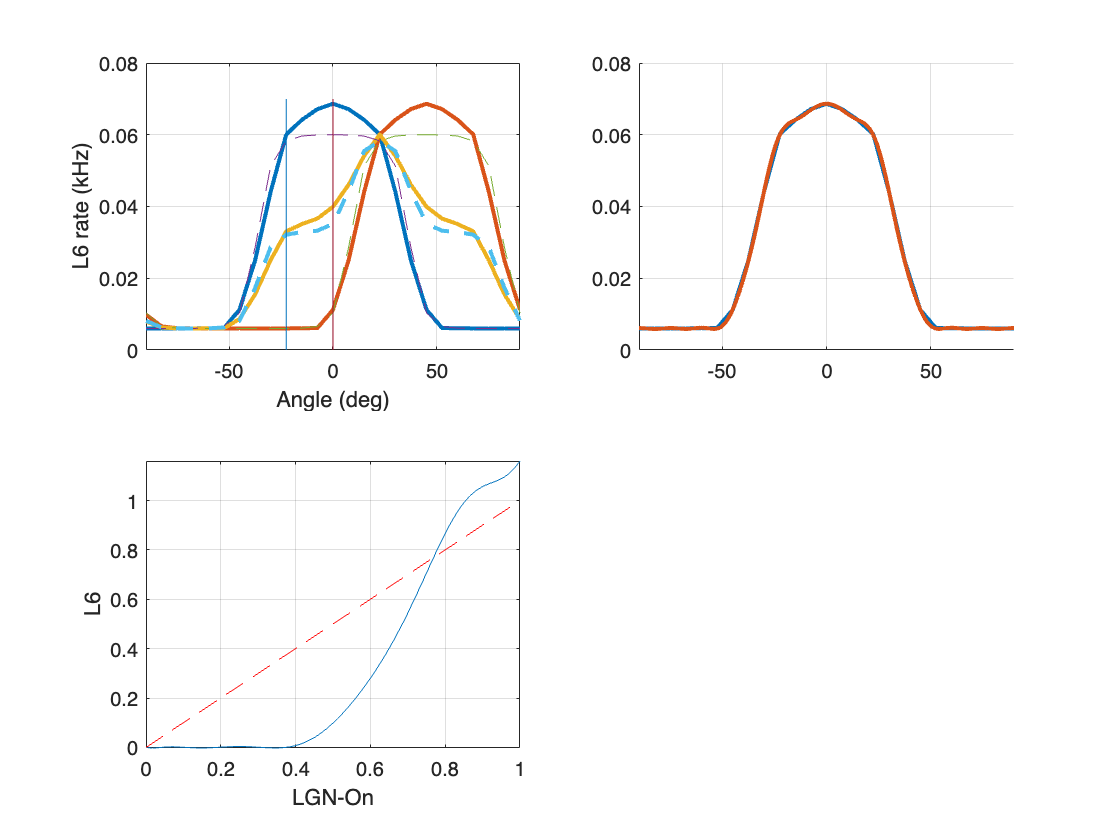


plot(AngAbs, L6_0deg, '--','DisplayName','0deg OD L6')
plot(AngAbs, L6_45deg, '--','DisplayName','45deg OD L6')
plot(AngAbs, (L6_45deg+L6_0deg)/2,'--', 'LineWidth',2,'DisplayName','22.5deg Pix L6')
xlim([-90 90])
plot(zeros(1,90),linspace(0,0.07,90))
plot(-22.5*ones(1,90),linspace(0,0.07,90))
xlabel('Angle (deg)')
ylabel('L6 rate (kHz)')

subplot 222
Y = fft(L6_0New(1:end-1));
N_dense = 1000; % For example, to make the output 5 times denser

% Prepare for higher resolution by zero-padding the frequency components
% The zeros are added symmetrically to maintain the signal's real-valued nature
Y_padded = [Y(1:floor(end/2)), zeros(1, N_dense-length(Y)), Y(floor(end/2)+1:end)];

% Perform IDFT on the modified frequency data
y_dense = ifft(Y_padded, 'symmetric');
y_dense = [y_dense,y_dense(1)];
y_dense = y_dense * max(L6_0New)/max(y_dense);
x_dense = linspace(-90,90,length(y_dense));

hold on
plot(AngAbs,L6_0New, 'LineWidth',2)
plot(x_dense, y_dense,'LineWidth',2)
grid on
xlim([-90 90])

subplot 223
ScaledLGN = (cosd(abs(mod(x_dense,180))*2)+1)/2;
ScaledL6 = (y_dense * 1e3 - L6low)/(L6up - L6low);
plot(ScaledLGN(1:floor(length(ScaledLGN)/2)),...
    ScaledL6(1:floor(length(ScaledLGN)/2)))
hold on
x = 0:0.1:1;
plot(x,x,'r--')
xlabel('LGN-On'); ylabel('L6')
grid on

tuningn by hand: LSY's version

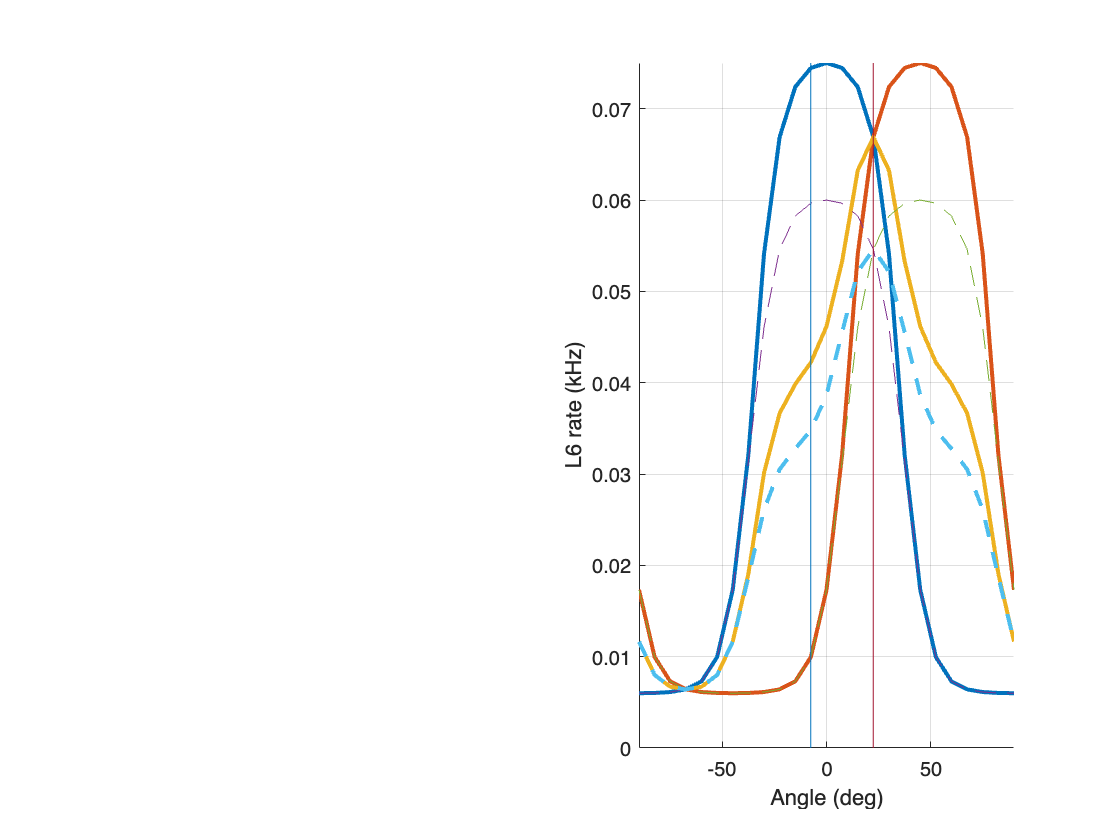

close all
figure
L6_225deg = (L6_45deg+L6_0deg)/2;

ampliFac = (0.07-0.03)/(0.06-0.03);
L6_0New = L6_0deg;
L6_0New(L6_0New> 0.03) = (L6_0New(L6_0New> 0.03)-0.03) * ampliFac + 0.03;
L6_45New = L6_45deg;
L6_45New(L6_45New> 0.03) = (L6_45New(L6_45New> 0.03)-0.03) * ampliFac + 0.03;
L6_225New = (L6_45New+L6_0New)/2;


subplot 121
hold on; grid on
plot(AngAbs,L6_0New, 'LineWidth',2,'DisplayName','0 deg Modified')
plot(AngAbs,L6_45New, 'LineWidth',2,'DisplayName','45 deg Modified')
plot(AngAbs,L6_225New, 'LineWidth',2,...
    'DisplayName',sprintf('30degFrac:%.2f',max(L6_225New)/L6_225New(12)))
plot(AngAbs, L6_0deg, '--','DisplayName','0deg OD L6')
plot(AngAbs, L6_45deg, '--','DisplayName','45deg OD L6')
plot(AngAbs, L6_225deg,'--', 'LineWidth',2,...
    'DisplayName',sprintf('30degFrac:%.2f',max(L6_225deg)/L6_225deg(12)))

plot(22.5*ones(1,90),linspace(0,0.075,90))
plot(-7.5*ones(1,90),linspace(0,0.075,90))

xlabel('Angle (deg)')
ylabel('L6 rate (kHz)')
%legend
ylim([0 0.075])
xlim([-90 90])

% Y = fft(L6_225deg(1:end-1));
% N_dense = 500; % For example, to make the output 5 times denser
% 
% % Prepare for higher resolution by zero-padding the frequency components
% % The zeros are added symmetrically to maintain the signal's real-valued nature
% Y_padded = [Y(1:floor(end/2)), zeros(1, N_dense-length(Y)), Y(floor(end/2)+1:end)];
% 
% % Perform IDFT on the modified frequency data
% y_dense = ifft(Y_padded, 'symmetric');
% y_dense = [y_dense,y_dense(1)];
% y_dense = y_dense * max(L6_225deg)/max(y_dense);
% x_dense = linspace(0,180,length(y_dense));
% 
% figure
% hold on
% plot(AngleUnique, (L6_45deg+L6_0deg)/2, 'LineWidth',2,'DisplayName','22.5deg Pix L6')
% plot(x_dense, y_dense,'r--','LineWidth',2)
% 
% L6zeroDeduc = reverseL6Angle(y_dense,45);
% plot(x_dense, L6zeroDeduc,'g--','LineWidth',2)
% plot(AngleUnique,L6_0deg)

find the best L6-LGN relation based on 22.5 curve

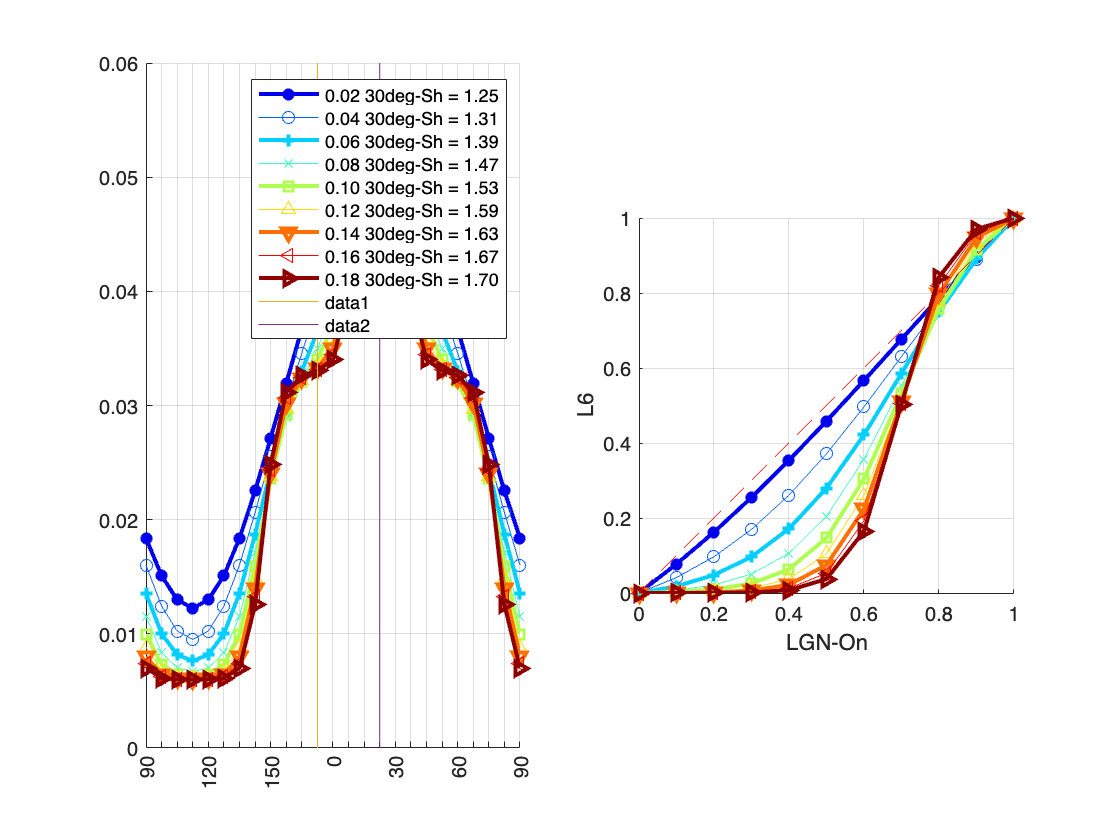

close all
figure

MarkerList = {'*','o','+','x','s','^',"v",'<','>','p'};
LW = [2,1/2,2,1/2,2,1/2,2,1/2,2,1/2,2];
L6IntesectAll = 0.4:0.05:0.8;
cmap = colormap('jet');
colordist = floor(length(cmap)/length(L6IntesectAll));

for L6Ind = 1:length(L6IntesectAll)
    %L6Intesect = L6IntesectAll(L6Ind);
    %L6Shape = 0.1;
    L6Intesect = 0.70;
    L6Shape = 0.02*L6Ind;
    L6End = 1;

    subplot 121
    hold on
    AngAbs = 0:7.5:(length(AngleUnique)-1)*7.5;
    AngAbs = AngAbs - AngAbs(AnglePlot == 0);
    ScaledLGNL6_0deg = (cosd(abs(mod(AngAbs,180))*2)+1)/2;
    ScaledLGNL6_45deg = (cosd(abs(mod(AngAbs-45,180))*2)+1)/2;
    L6_0deg = (rescaledSigmoid(ScaledLGNL6_0deg, L6Intesect, L6Shape) * L6End * (L6up-L6low) + L6low) /1e3;
    L6_45deg = (rescaledSigmoid(ScaledLGNL6_45deg, L6Intesect, L6Shape) * L6End * (L6up-L6low) + L6low) /1e3;
    %plot(AngAbs, L6_0deg, '--','DisplayName','0deg OD L6')
    %plot(AngAbs, L6_45deg, '--','DisplayName','45deg OD L6')
    L6_225pix = (L6_45deg+L6_0deg)/2;
    %DPName = sprintf('%.2f 30degRto = %.2f',L6Intesect,max(L6_225pix)/L6_225pix(12));
    DPName = sprintf('%.2f 30deg-Sh = %.2f',L6Shape,max(L6_225pix)/L6_225pix(12));
    plot(AngAbs, L6_225pix, ...
        'Marker',MarkerList{L6Ind},'LineWidth',LW(L6Ind),'Color',cmap(colordist*L6Ind,:),...
        'DisplayName',DPName)

    subplot 122
    hold on;
    x = 0:0.1:1;
    plot(x,rescaledSigmoid(x, L6Intesect, L6Shape),...
        'Marker',MarkerList{L6Ind},'LineWidth',LW(L6Ind),'Color',cmap(colordist*L6Ind,:));
    plot(x,x,'r--')
    xlabel('LGN-On'); ylabel('L6')
    grid on
    axis square
end
subplot 121
plot(AngAbs(12)*ones(7,1),0:0.01:0.06)
plot(AngAbs(16)*ones(7,1),0:0.01:0.06)
xtickAng = AnglePlot;
xlim([-90 90]); ylim([0 0.06]); grid on
set(gca,'xtick',AngAbs,'xticklabel',xtickLab)
legend